# Solving System of Linear Equations

## First Part

The following figure shows a flat square plate with its side held at constant temperature. Find the temperature at each node x1, x2,x3,x4. Each dot represent a node, and the temperature at each node is assumed to be given by the average temperature of adjacent nodes. 

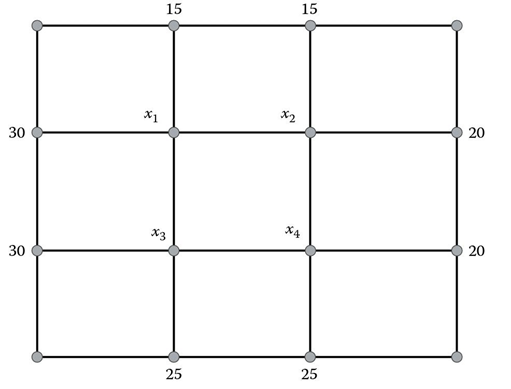


$$4x_1 -x_2 -x_3 =45$$



$$-x_1 +4x_2 -x_4 =35$$



$$-x_1 +4x_3 -x_4 =55$$



$$-x_2 -x_3 +4x_4 =45$$



$$\begin{array}{l}
\left\lbrack A\right\rbrack *\left\lbrack x\right\rbrack =\left\lbrack B\right\rbrack \\
{\left\lbrack A\right\rbrack }^{-1} *\left\lbrack A\right\rbrack *\left\lbrack x\right\rbrack ={\left\lbrack A\right\rbrack }^{-1} *\left\lbrack B\right\rbrack 
\end{array}$$


clear, clc 
A = [4 -1 -1 0;
    -1 4 0 -1;
    -1 0 4 -1;
    0 -1 -1 4]

A =      4    -1    -1     0
    -1     4     0    -1
    -1     0     4    -1
     0    -1    -1     4


B = [45 35 55 45]'

B =     45
    35
    55
    45


x = pinv(A)*B

x =    22.5000
   20.0000
   25.0000
   22.5000


X = linsolve(A,B)

X =    22.5000
   20.0000
   25.0000
   22.5000


## Second Part

Illustrate the temperature profile of plate as heat map and 3D plot. (Assume the temperature of corner nodes is equal to 25℃)

Temp = ones(4,4);
for i=1:4
    for j=1:4
        if (i==1 && j==1) || (i==1 && j==4) || (i==4 && j==1) || (i==4 && j==4)
            Temp(i,j) = 25; %Degree Celcius
        elseif (i==1) && (j==2 || j==3)
            Temp(i,j) = 15;
        elseif (j==1) && (i==2 || i==3)
            Temp(i,j) = 30;
        elseif (i==4) && (j==2 || j==3)
            Temp(i,j) = 25;
        elseif (j==4) && (i==2 || i==3)
            Temp(i,j) = 20;
        end
    end
end
Temp(2,2) = X(1);
Temp(2,3) = X(2);
Temp(3,2) = X(3);
Temp(3,3) = X(4);

disp(Temp)

   25.0000   15.0000   15.0000   25.0000
   30.0000   22.5000   20.0000   20.0000
   30.0000   25.0000   22.5000   20.0000
   25.0000   25.0000   25.0000   25.0000



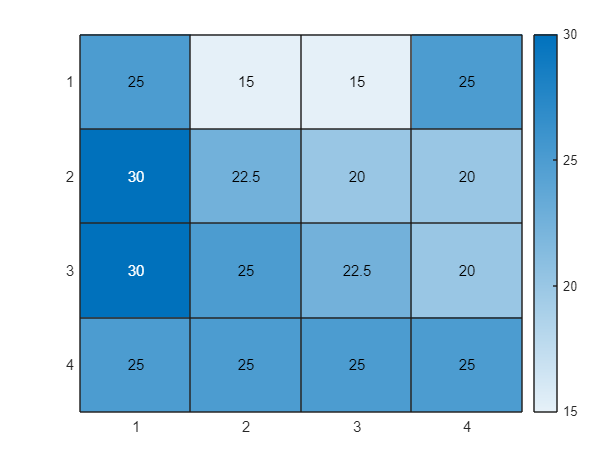

figure(1)
heatmap(Temp)

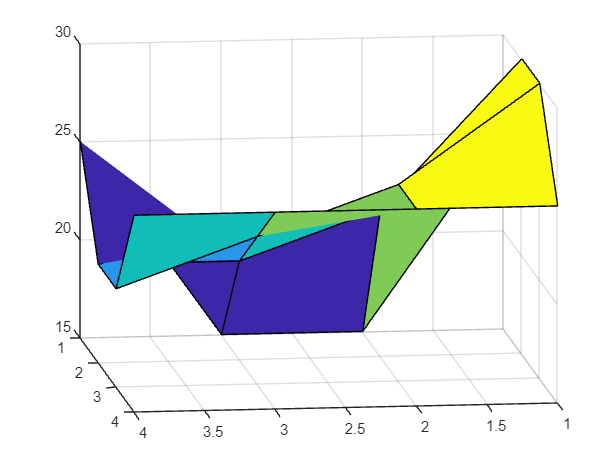


figure(2)
surf(Temp)